# Presentación Final: Ejercicio 2

En esta actividad final se obtiene la matriz de transformación T empleando variables simbólicas y de esta manera obtener la cinemática diferencial con la velocidad lineal y angular. El sistema que se analizará es el siguiente modelo de piernas robóticas:

 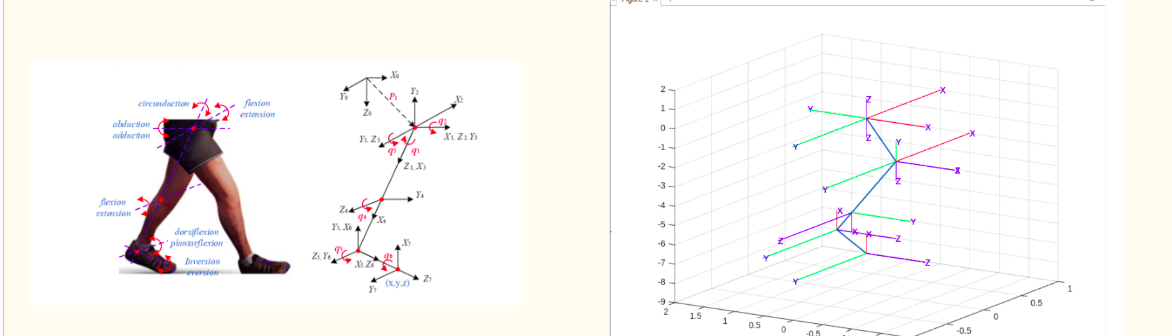

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) th7(t) th8(t) %Angulos de 
syms t
% cada articulación
syms th1p(t)  th2p(t) th3p(t) th4p(t) th5p(t) th6p(t) th7p(t) th8p(t) %Velocidades
% de cada articulación
syms a0 a1 a2 a3 a4 a5 a6 a7 a8 %longitudes

%Configuración del robot
RP=[0 0 0 0 0 0];

Q= [th1; th2; th3; th4; th5; th6 ;th7; th8];
%disp('Coordenadas generalizadas');
pretty (Q);

/ th1(t) \
|        |
| th2(t) |
|        |
| th3(t) |
|        |
| th4(t) |
|        |
| th5(t) |
|        |
| th6(t) |
|        |
| th7(t) |
|        |
\ th8(t) /



%Creamos el vector de velocidades generalizadas
%Qp= diff(Q, t);
Qp=[th1p; th2p; th3p; th4p; th5p; th6p; th7p; th8p];
%disp('Velocidades generalizadas');
pretty (Qp);

/ th1p(t) \
|         |
| th2p(t) |
|         |
| th3p(t) |
|         |
| th4p(t) |
|         |
| th5p(t) |
|         |
| th6p(t) |
|         |
| th7p(t) |
|         |
\ th8p(t) /



%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%H1 
%Posición de la articulación 1
P(:,:,1)= [a0;a0;a0];
%Matriz de rotación de la junta 1. 
R(:,:,1)= [(cos(th1+th2)+cos(th1-th2))/2  (-sin(th1+th2)+sin(th1-th2))/2  sin(th1);
           sin(th2)  cos(th2)  0;
           (-sin(th1+th2)-sin(th1-th2))/2  (-cos(th1+th2)+cos(th1-th2))/2  cos(th1)];  

%H2
%Posición de la articulación 2
P(:,:,2)= [a1; 0; a2];
%Matriz de rotación de la junta 2  NO HAY ROTACIÓN
R(:,:,2)= [1 0 0;
           0 1 0;
           0 0 1];

%H3 
%Posición de la articulación 3
P(:,:,3)= [0; 0; 0];
%Matriz de rotación de la junta 3
R(:,:,3)=   [cos(th3) (-cos(th3+th4)+cos(th3-th4))/2  (sin(th3+th4)+sin(th3-th4))/2;
              0  cos(th4)  -sin(th4);
            -sin(th3)    (sin(th3+th4)-sin(th3-th4))/2  (cos(th3+th4)+cos(th3-th4))/2];

%H4
%Posición de la articulación 4
P(:,:,4)= [0; a3; a4];
%Matriz de rotación de la junta 4
R(:,:,4)=   [cos(th5) (-sin(th5+th6)-sin(th5-th6))/2  (-cos(th5+th6)+cos(th5-th6))/2;
             sin(th5)  (cos(th5+th6)+cos(th5-th6))/2  (-sin(th5+th6)+sin(th5-th6))/2;
              0         sin(th6)        cos(th6)];

%H5
%Posición de la articulación 5
P(:,:,5)= [a5; a6; 0];
%Matriz de rotación de la junta 5
R(:,:,5)=   [cos(th7) (-sin(th7+th8)-sin(th7-th8))/2  (-cos(th7+th8)+cos(th7-th8))/2;
             sin(th7)  (cos(th7+th8)+cos(th7-th8))/2  (-sin(th7+th8)+sin(th7-th8))/2;
              0         sin(th8)        cos(th8)];

%H6
%Posición de la articulación 6
P(:,:,6)= [a7; 0; a8];
%Matriz de rotación de la junta 6 NO HAY ROTACIÓN
R(:,:,6)= [1 0 0;
           0 1 0;
           0 0 1];


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/  cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), sin(th1(t)), a0 \
|                                                                     |
|        sin(th2(t)),              cos(th2(t)),            0,      a0 |
|                                                                     |
| -cos(th2(t)) sin(th1(t)),  sin(th1(t)) sin(th2(t)), cos(th1(t)), a0 |
|                                                                     |
\             0,                        0,                 0,       1 /



Matriz de Transformación global T2


/  cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), sin(th1(t)), a0 + a2 sin(th1(t)) + a1 cos(th1(t)) cos(th2(t)) \
|                                                                                                                   |
|        sin(th2(t)),              cos(th2(t)),            0,                     a0 + a1 sin(th2(t))               |
|                                                                                                                   |
| -cos(th2(t)) sin(th1(t)),  sin(th1(t)) sin(th2(t)), cos(th1(t)), a0 + a2 cos(th1(t)) - a1 cos(th2(t)) sin(th1(t)) |
|                                                                                                                   |
\             0,                        0,                 0,                              1                        /



Matriz de Transformación global T3


/  cos(th1(t)) cos(th2(t)) cos(th3(t)) - sin(th1(t)) sin(th3(t)),  cos(th3(t)) sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)) sin(th2(t)) + cos(th1(t)) cos(th2(t)) sin(th3(t)) sin(th4(t)), cos(th3(t)) cos(th4(t)) sin(th1(t)) + cos(th1(t)) sin(th2(t)) sin(th4(t)) + cos(th1(t)) cos(th2(t)) cos(th4(t)) sin(th3(t)), a0 + a2 sin(th1(t)) + a1 cos(th1(t)) cos(th2(t)) \
|                                                                                                                                                                                                                                                                                                                                                                             |
|                     cos(th3(t)) sin(th2(t)),                                                    cos(th2(t)) cos(th4(t)) + sin(th2(t)) sin(th3(t)) sin(th4(t)),                                                               cos(th4(t)) sin(th2(t)) sin(th3(t)) - cos

Matriz de Transformación global T4


/            sin(th5(t)) #2 - cos(th5(t)) #7,                      sin(th6(t)) #5 + cos(th5(t)) cos(th6(t)) #2 + cos(th6(t)) sin(th5(t)) #7,                      cos(th6(t)) #5 - cos(th5(t)) sin(th6(t)) #2 - sin(th5(t)) sin(th6(t)) #7,           a0 + a2 sin(th1(t)) + a1 cos(th1(t)) cos(th2(t)) - a3 cos(th1(t)) cos(th4(t)) sin(th2(t)) + a4 cos(th3(t)) cos(th4(t)) sin(th1(t)) + a3 cos(th3(t)) sin(th1(t)) sin(th4(t)) + a4 cos(th1(t)) sin(th2(t)) sin(th4(t)) + a3 cos(th1(t)) cos(th2(t)) sin(th3(t)) sin(th4(t)) + a4 cos(th1(t)) cos(th2(t)) cos(th4(t)) sin(th3(t)) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                

Matriz de Transformación global T5


/ sin(th7(t)) #2 - cos(th7(t)) #5,  cos(th7(t)) cos(th8(t)) #2 - sin(th8(t)) #7 + cos(th8(t)) sin(th7(t)) #5,  - cos(th8(t)) #7 - cos(th7(t)) sin(th8(t)) #2 - sin(th7(t)) sin(th8(t)) #5, a0 + a2 sin(th1(t)) + a1 cos(th1(t)) cos(th2(t)) - a3 cos(th1(t)) cos(th4(t)) sin(th2(t)) + a4 cos(th3(t)) cos(th4(t)) sin(th1(t)) + a3 cos(th3(t)) sin(th1(t)) sin(th4(t)) + a4 cos(th1(t)) sin(th2(t)) sin(th4(t)) - a5 cos(th5(t)) sin(th1(t)) sin(th3(t)) + a3 cos(th1(t)) cos(th2(t)) sin(th3(t)) sin(th4(t)) - a5 cos(th1(t)) cos(th4(t)) sin(th2(t)) sin(th5(t)) + a6 cos(th3(t)) cos(th4(t)) sin(th1(t)) sin(th6(t)) + a5 cos(th3(t)) sin(th1(t)) sin(th4(t)) sin(th5(t)) + a6 cos(th1(t)) sin(th2(t)) sin(th4(t)) sin(th6(t)) + a6 cos(th6(t)) sin(th1(t)) sin(th3(t)) sin(th5(t)) + a5 cos(th1(t)) cos(th2(t)) cos(th3(t)) cos(th5(t)) + a4 cos(th1(t)) cos(th2(t)) cos(th4(t)) sin(th3(t)) - a6 cos(th1(t)) cos(th2(t)) cos(th3(t)) cos(th6(t)) sin(th5(t)) - a6 cos(th1(t)) cos(th4(t)) cos(th5(t)) cos(th6(t)) sin(th2(t)) + a6 

Matriz de Transformación global T6


/ sin(th7(t)) #2 - cos(th7(t)) #5,    cos(th7(t)) cos(th8(t)) #2 - sin(th8(t)) #7 + cos(th8(t)) sin(th7(t)) #5,   - cos(th8(t)) #7 - cos(th7(t)) sin(th8(t)) #2 - sin(th7(t)) sin(th8(t)) #5, a0 + a2 sin(th1(t)) + a1 cos(th1(t)) cos(th2(t)) - a3 cos(th1(t)) cos(th4(t)) sin(th2(t)) + a4 cos(th3(t)) cos(th4(t)) sin(th1(t)) + a3 cos(th3(t)) sin(th1(t)) sin(th4(t)) + a4 cos(th1(t)) sin(th2(t)) sin(th4(t)) - a5 cos(th5(t)) sin(th1(t)) sin(th3(t)) + a3 cos(th1(t)) cos(th2(t)) sin(th3(t)) sin(th4(t)) - a5 cos(th1(t)) cos(th4(t)) sin(th2(t)) sin(th5(t)) + a6 cos(th3(t)) cos(th4(t)) sin(th1(t)) sin(th6(t)) - a7 cos(th5(t)) cos(th7(t)) sin(th1(t)) sin(th3(t)) + a5 cos(th3(t)) sin(th1(t)) sin(th4(t)) sin(th5(t)) + a6 cos(th1(t)) sin(th2(t)) sin(th4(t)) sin(th6(t)) + a6 cos(th6(t)) sin(th1(t)) sin(th3(t)) sin(th5(t)) + a5 cos(th1(t)) cos(th2(t)) cos(th3(t)) cos(th5(t)) + a4 cos(th1(t)) cos(th2(t)) cos(th4(t)) sin(th3(t)) + a7 cos(th1(t)) cos(th2(t)) cos(th3(t)) cos(th5(t)) cos(th7(t)) - a6 cos(th1(t

% %Calculamos el jacobiano lineal de forma diferencial
% %disp('Jacobiano lineal obtenido de forma diferencial');
% %Derivadas parciales de x respecto a th1 y th2
% Jv11= functionalDerivative(PO(1,1,GDL), th1);
% Jv12= functionalDerivative(PO(1,1,GDL), th2);
% Jv13= functionalDerivative(PO(1,1,GDL), th3);
% %Derivadas parciales de y respecto a th1 y th2
% Jv21= functionalDerivative(PO(2,1,GDL), th1);
% Jv22= functionalDerivative(PO(2,1,GDL), th2);
% Jv23= functionalDerivative(PO(2,1,GDL), th3);
% %Derivadas parciales de z respecto a th1 y th2
% Jv31= functionalDerivative(PO(3,1,GDL), th1);
% Jv32= functionalDerivative(PO(3,1,GDL), th2);
% Jv33= functionalDerivative(PO(3,1,GDL), th3);
% 
% %Creamos la matríz del Jacobiano lineal
% jv_d=simplify([Jv11 Jv12 Jv13;
%               Jv21 Jv22 Jv23;
%               Jv31 Jv32 Jv33]);
% %pretty(jv_d);

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0
            % con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

Q_p = sym('Qp', [1, length(Q)]);
%disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Q_p');

pretty(V);

/                                                                                                                                                       ___                                                                                                                                                                                                                                                                                                                                                    ___                                                                                                                                                                                                                                  ___                                                                                                                                                                                                                                                                                 

%disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Q_p');
    pretty(W);

/               ___         ___                           ___                                                                                                                                                                                                          \
|  0,  #1, #1,  Qp1 #10,  - Qp1 #4,                     - Qp1 (cos(th8(t)) #4 + cos(th7(t)) sin(th8(t)) (sin(th6(t)) #10 + cos(th5(t)) cos(th6(t)) #9 + cos(th6(t)) sin(th5(t)) #11) + sin(th7(t)) sin(th8(t)) (cos(th5(t)) #11 - sin(th5(t)) #9))                     |
|                                                                                                                                                                                                                                                                      |
|                ___        ___     ___                                                                                                                                                                      